A=2461.945

A = 2.4619e+03

a=0.899

a = 0.8990

B=9455

B = 9455

b=0.874

b = 0.8740

t=20

t = 20

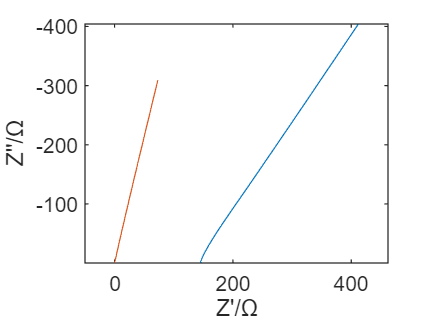


data_sample=data_20220707_inline_0(1:2,:);
data_sample(2,:)=data_20220707_inline_0((t+1),:);
f=data_sample(1,:);
Zcpe=A./(f.^a)-1i*B./(f.^b);
data_cpe=data_sample;
data_cpe(2,:)=Zcpe;
Zres=sub_sys(data_sample,data_cpe);
Zres(2,:)=Zres(2,:);
% Zres(2,:)=1./(1./Zres(2,:)-1/r)
figure()
plotcplx_all_test(data_sample)
hold on
plotcplx_all_test(data_cpe)

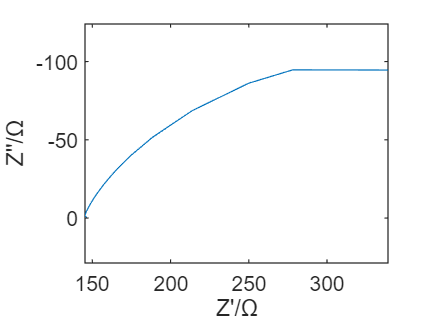

figure()
plotcplx_all_test(Zres)